# Tutorial 8: Workspace Analysis (Part 3)

This tutorial will show how workspace analysis can be run in CASPR for cable-driven robots. This tutorial will use the ideas from the following previous tutorials:

- `T1_load_robot.mlx`

- `T8_workspace_analysis_1.mlx`

Part 3 of this tutorial will focus on:

- Using the `PointWorkspaceSimulator` to compute the workspace with metrics.

- Computing the workspace through writing your own loop

clear;

## Setup (required for both approaches)

### Load the robot 

Load the 2 DoF robot in the manner shown in `T1_load_robot.mlx`.

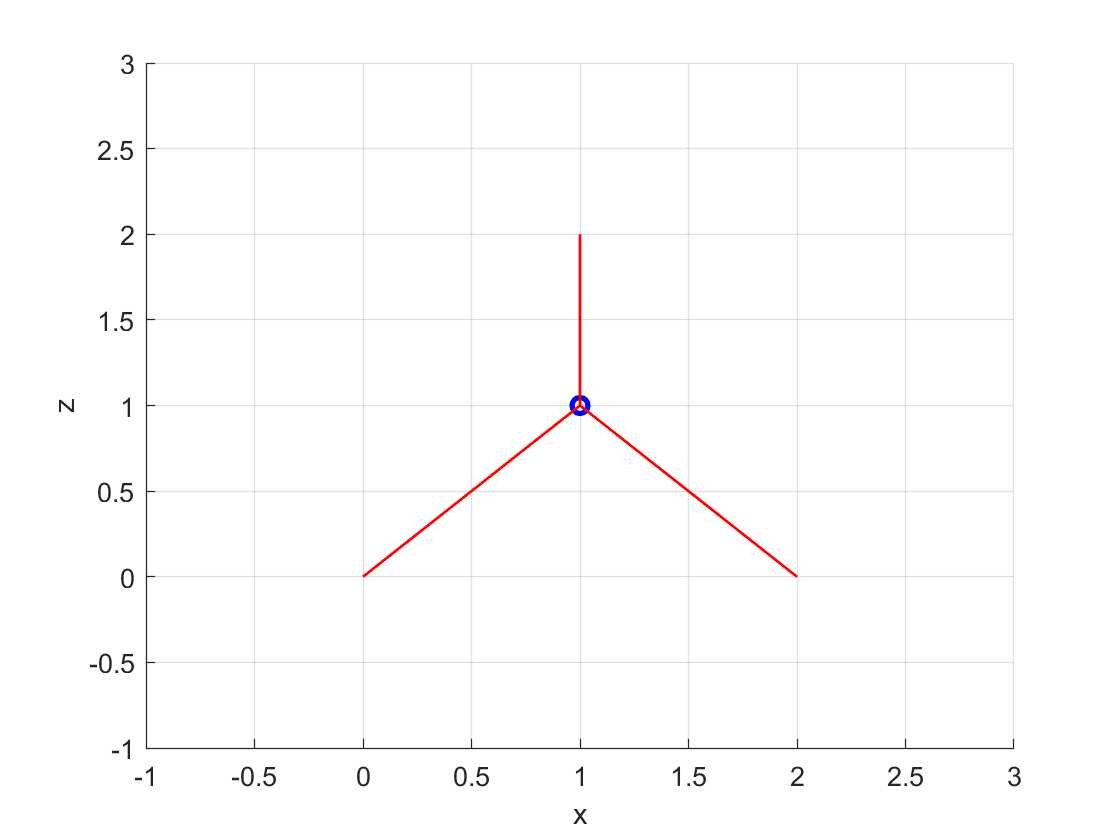

model_config = ModelConfig('Example point mass XZ');
cdpr_model = model_config.getModel('3_cables');
MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot

### Setup the point-wise grid

A uniform (equal spacing) grid will be setup representing the set of points which the workspace analysis will be run.

% Set up the workspace simulator
% First the grid
q_min           = [0.05; -2.0];
q_max           = [1.95; 1.95];
q_step          = 0.05*ones(cdpr_model.numDofs, 1); 
uniform_grid    = UniformGrid(q_min, q_max, q_step, 'step_size');

### Setup plotting

dofs_to_plot = [1 2]; % Plot X axis as first DoF and Y axis as second DoF

### Setup static workspace condition

Create the workspace condition:

ws_condition_static = WorkspaceStaticCondition();

### Setup workspace metrics

For the types of metrics that can be studied, refer to the `~/src/Analysis/Workspace/JointSpaceWorkspace/Points/Metrics`. A few examples will be shown here.

Starting with the `TensionFactor` metric:

metric_tension_factor = TensionFactorModifiedMetric();
metric_unilateral_dexterity = UnilateralDexterityMetric();

## 1) Solve using the PointWorkspaceSimulator

Create the simulator object using the robot model, grid, workspace condition and metrics:

ws_sim = PointWorkspaceSimulator(cdpr_model, uniform_grid, {ws_condition_static}, {metric_tension_factor, metric_unilateral_dexterity}, []);

Run the simulator over the specified grid:

ws_sim.run();

[INFO] Workspace point 1. Completion Percentage: 0.03

No feasible solution found.

Linprog stopped because no point satisfies the constraints.


The problem is infeasible.

During presolve, quadprog found the constraints to be inconsistent 
to within the constraint tolerance.

[INFO] Workspace point 2. Completion Percentage: 0.06

No feasible solution found.

Linprog stopped because no point satisfies the constraints.


The problem is infeasible.

During preso

Finally, plot the resulting 2-D workspace. By default, all of the workspace conditions and metrics will be plotted.

w_handles = ws_sim.workspace.plotWorkspace(dofs_to_plot);

The default order follows the order of the metrics input to the `PointWorkspaceSimulator`.

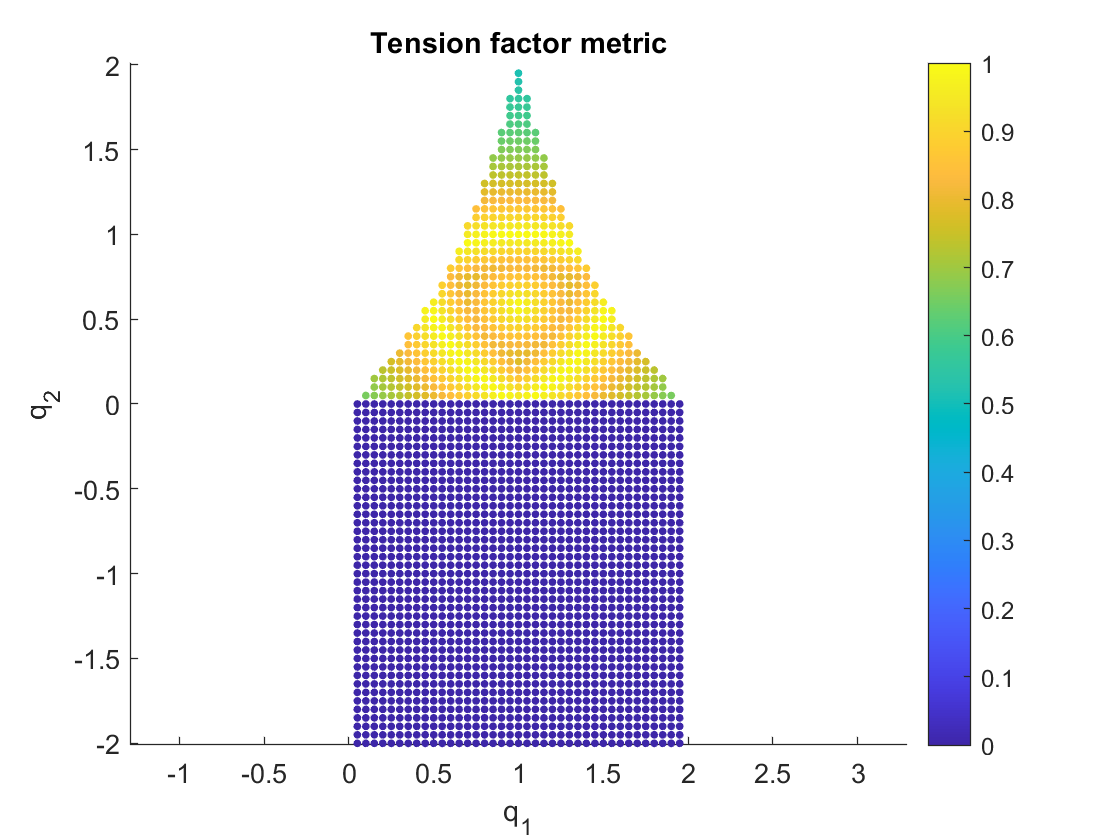

figure(w_handles(1));
axis equal;
title('Tension factor metric');

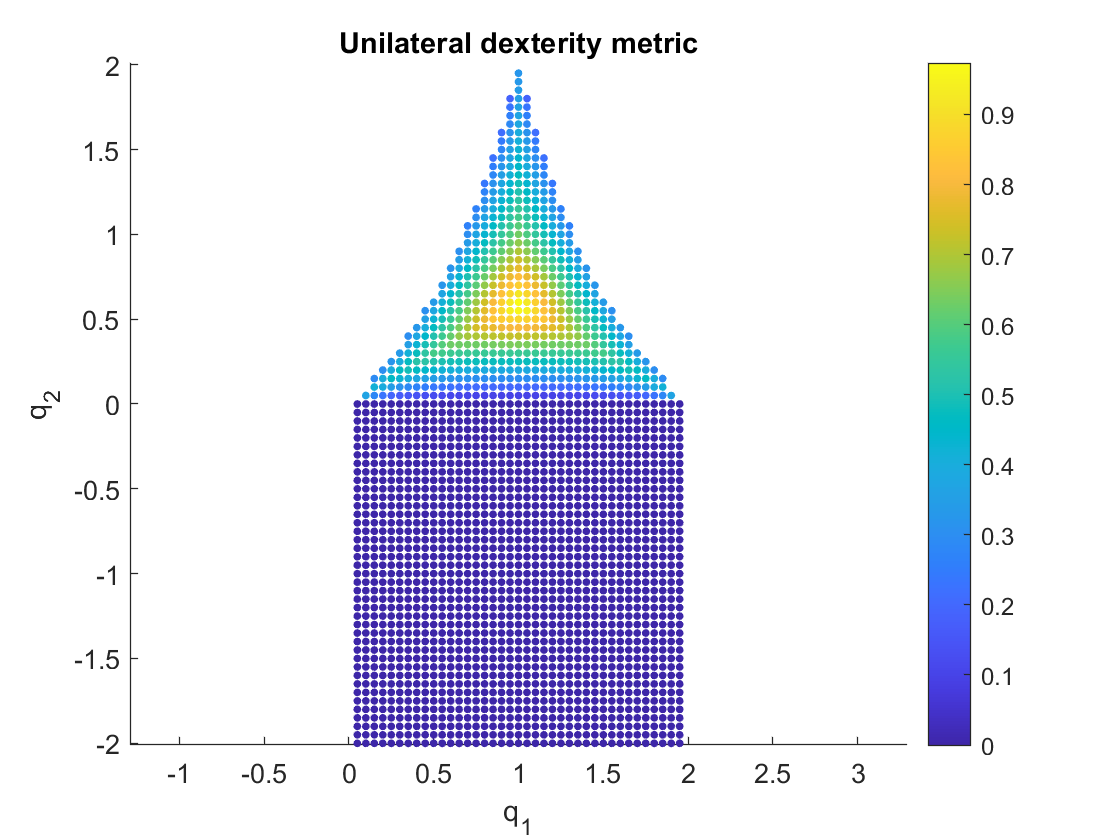

figure(w_handles(2));
axis equal;
title('Unilateral dexterity metric');

To plot the workspace condition with no metric, input `[0]` for the indices of the metric:

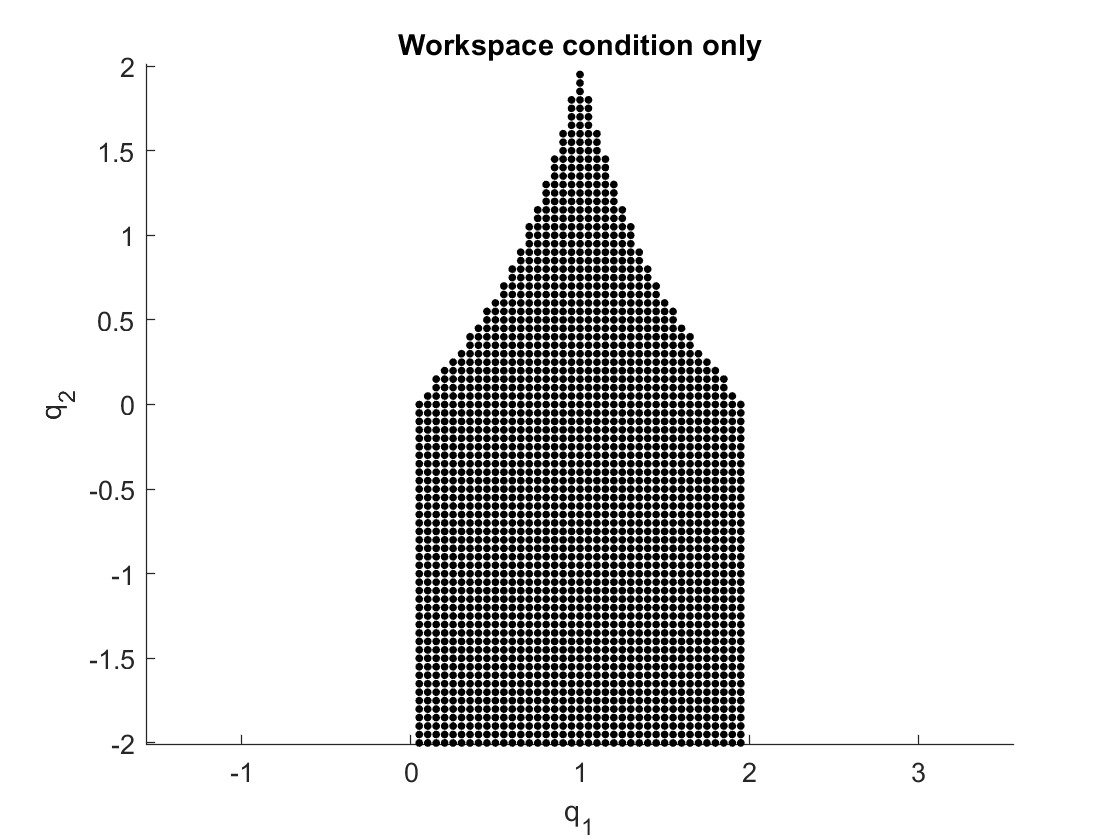

ws_sim.workspace.plotWorkspace(dofs_to_plot, [1], [0]);
axis equal;
title('Workspace condition only');

To plot just the metrics with no workspace condition, input `[0]` for the indices of the condition:

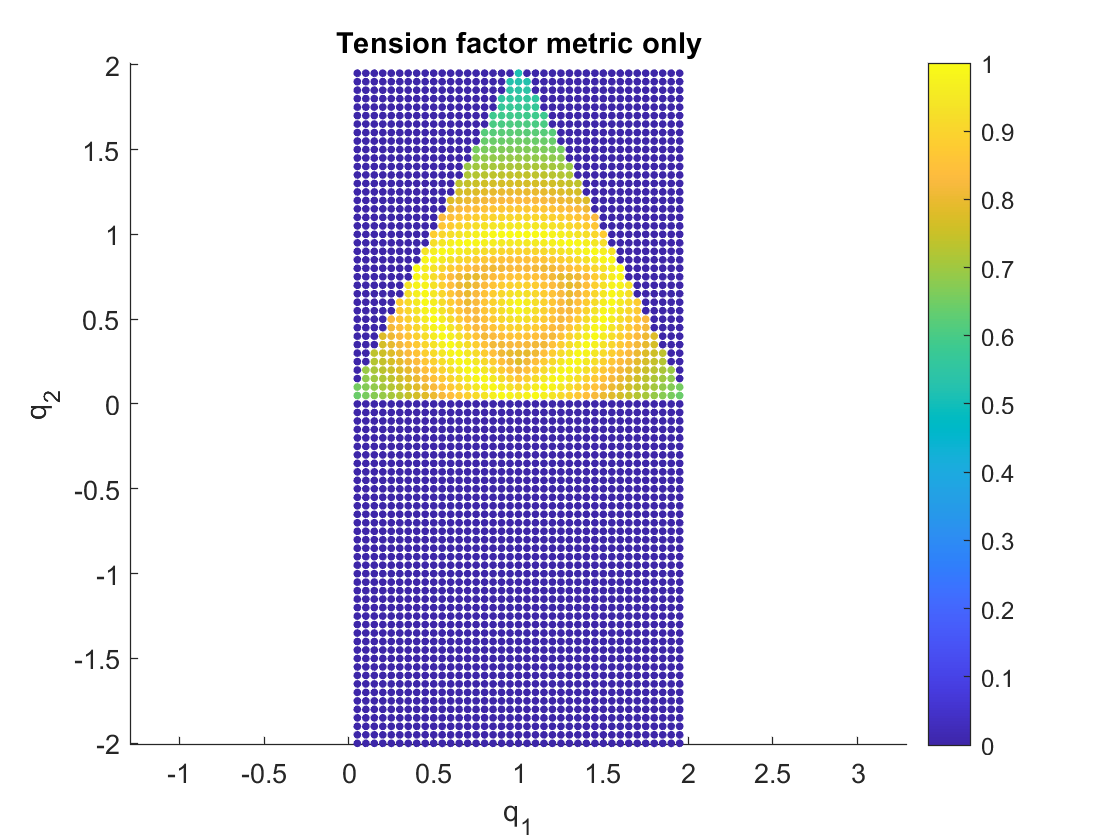

w_handles = ws_sim.workspace.plotWorkspace(dofs_to_plot, [0], []);
figure(w_handles(1));
axis equal;
title('Tension factor metric only');

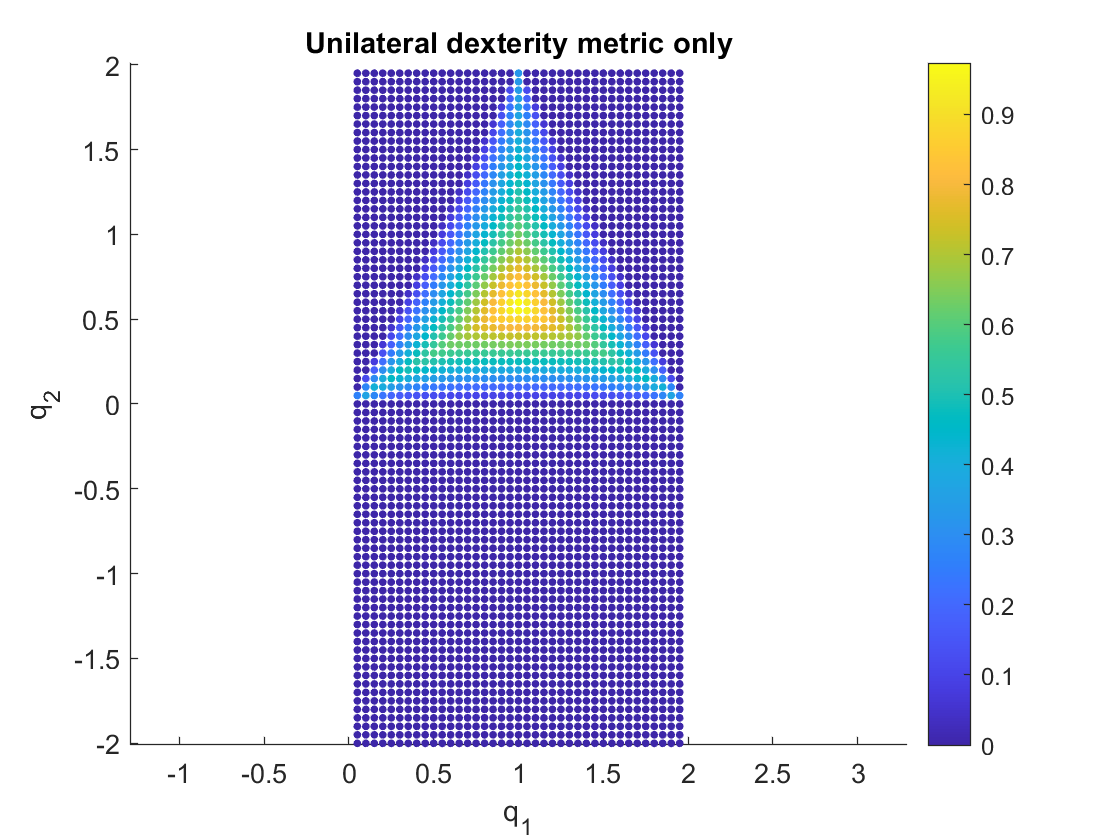

figure(w_handles(2));
axis equal;
title('Unilateral dexterity metric only');

Or to just plot just the `UnilateralDexterityMetric` (`[2]`) single metric for the `WorkspaceStaticCondition `(`[1]`):

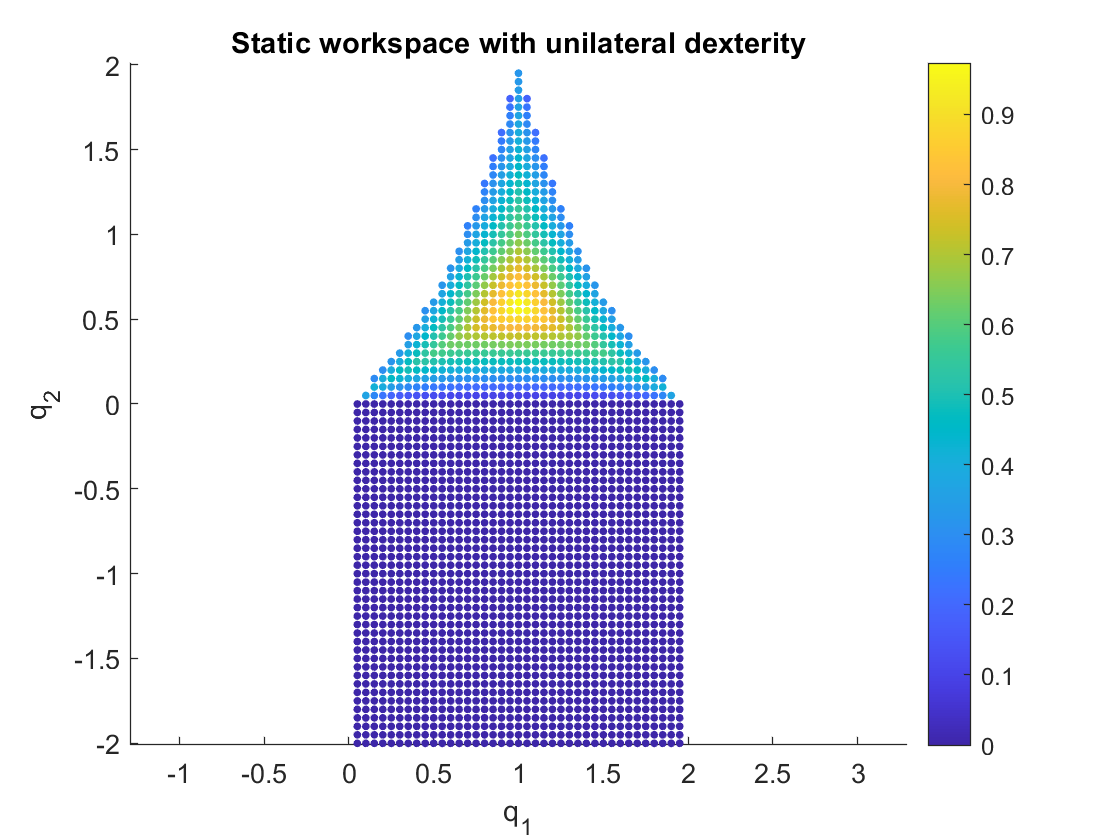

ws_sim.workspace.plotWorkspace(dofs_to_plot, [1], [2]);
axis equal;
title('Static workspace with unilateral dexterity');

## 2) Writing your own loop